flights=importFlightsData("flightsJan.csv")

flights = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________

data=groupsummary(flights,"ORIGIN","none");
data=sortrows(data,"GroupCount","descend")

data = 312×2 table
    ORIGIN    GroupCount
    ______    __________

     ATL        29512   
     ORD        23484   
     DFW        23153   
     LAX        17340   
     DEN        17090   
     IAH        13376   
     PHX        13122   
     SFO        12891   
     LAS        11604   
     MCO        10083   
     LGA         9517   
     DTW         9473   
     CLT         9350   
     MSP         8903   
     BOS         8837   
     EWR         8697   


Question 2:

data2=groupsummary(flights,"ORIGIN","mean","DISTANCE");
data2=sortrows(data2,"mean_DISTANCE","ascend")

data2 = 312×3 table
    ORIGIN    GroupCount    mean_DISTANCE
    ______    __________    _____________

     WRG          62             56.5    
     PSG          62               77    
     CSG          80               83    
     CLD         204               86    
     ACT         147               89    
     PUB          53              109    
     LAR          62              113    
     SPS         106              113    
     TYR         193           115.27    
     BRD          54           115.44    
     MKG          62              118    
     FLG         142              119    
     SIT          92           124.65    
     VEL          53              132    
     SMX          60              134    
     GGG          54              140    


Question 3:

data3=flights(flights.CANCELLED==1,:);
data3=groupsummary(data3,"ORIGIN","sum","CANCELLED");
sum(data3.sum_CANCELLED)

ans = 11982

Question 4:

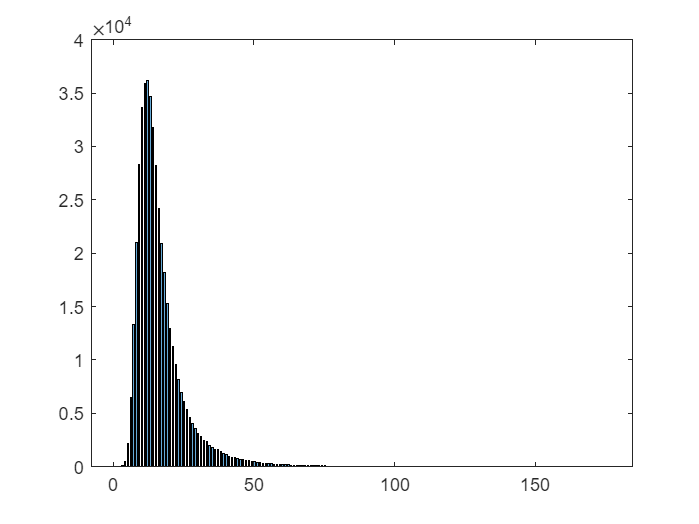

taxiout=flights.TAXI_OUT;
histogram(taxiout)